% Example Input (Replace with actual data)
flattened_surface = obj_2D.vt;  % Flattened 2D vertex positions
flattened_surface = [flattened_surface,zeros(size(flattened_surface,1),1)];
deployed_surface = obj_2D.v;    % Deployed 3D vertex positions
faces = obj_2D.f.v

faces =    110     2     1
   111     3     2
   112     4     3
   113     5     4
   114     6   113
   115     7   114
   116     8   115
   117     9     8
   118    10   117
   119    11   118



% Move and rotate the 3D object to match the boundary
% Rotate object 
deployed_surface = [deployed_surface(:,1), -deployed_surface(:,3),deployed_surface(:,2)];  

% Move to match the coorespoind node
T = mean(flattened_surface) - mean(deployed_surface);

flattened_surface = flattened_surface - [T(:,[1,2]),0];


## Plot the 3D configuration and 2D configuration

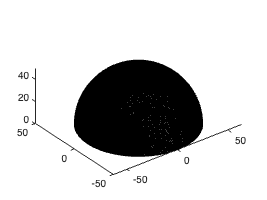

% Plot the results
% Plot the 3D configurations
figure()
patch('Vertices', deployed_surface, 'Faces', faces, ...
      'FaceColor','none', 'EdgeColor', 'black');
axis equal;          % Equal scaling for all axes
%axis off;
view(3);             % Set default 3D view angle

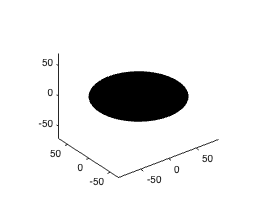


figure()
axis equal;
patch('Vertices', flattened_surface, 'Faces', faces, ...
    'FaceColor', 'none', 'EdgeColor', 'black'); % Plot 2D figure
view(3);             % Set default 3D view angle

## Deploy the 2D configuration

% % Initialize figure for visualization
% fig = figure('Color', 'w');
% hold on;
% xlabel('X'); ylabel('Y'); zlabel('Z');
% view(45, 30);
% grid on; axis equal;
% 
% alpha_values = linspace(0, 1, 100); % Transition from flattened to
% 
% % Loop through alpha values to interpolate and visualize
% for alpha = alpha_values
%     % Interpolate between flattened and deployed surfaces
%     V_deploy = (1 - alpha) * flattened_surface + alpha * deployed_surface;
% 
%     % Clear previous plot and render the current configuration
%     cla; % Clear axes
%     patch('Faces', obj_2D.f.v, 'Vertices', V_deploy, ...
%         'FaceColor', 'None', 'EdgeColor', 'Black'); % Render faces
% 
%     title(['Alpha = ', num2str(alpha)]);
%     view(45, 30); % Fix the view angle
%     drawnow
% end
% 
% hold off;


## **Interactive figure**

% % Deploy a flattened surface onto the deployed surface (conformal mapping)
% % using interpolation and analysis.
% % Input: flattened_surface (vertices, faces)
% %        deployed_surface (vertices, faces)
% 
% % Example Input (Replace with your actual data)
% flattened_surface = obj_2D.vt;  % Flattened 2D vertex positions
% deployed_surface = obj_3D.v;    % Deployed 3D vertex positions
% faces = obj_2D.f.v;             % Face connectivity
% 
% 
% % Move the deployed surface and flattned surface onto the same platform
% 
% 
% num = 20; % Number of steps in deployment
% alpha = linspace(0,1,num); % Deployment parameter
% 
% % Step 4: Visualization Loop for Deployment Animation
% figure;
% for k = 1:num
%     % Compute interpolated deployment shape
%     X_deploy = (1-alpha(k)) * flattened_surface(:,1) + alpha(k) * deployed_surface(:,1);
%     Y_deploy = (1-alpha(k)) * flattened_surface(:,2) + alpha(k) * deployed_surface(:,2);
%     Z_deploy = alpha(k) * deployed_surface(:,3);  % Gradually lift into 3D
% 
%     V_deploy = [X_deploy, Y_deploy, Z_deploy];
% 
%     % Plotting
%     patch('Vertices', V_deploy, 'Faces', faces, ...
%           'FaceColor', 'cyan', 'EdgeColor', 'blue', 'FaceAlpha', 0.6); % Transparent surface
%     
%     hold on;
%     plot3(X_deploy, Y_deploy, Z_deploy, 'k.'); % Mesh points
%     hold off;
%     
%     axis equal; grid on;
%     xlabel('X'); ylabel('Y'); zlabel('Z');
%     title(['Deployment Step: ' num2str(k) ' / ' num2str(num)]);
%     
%     % Rotate view dynamically
%     %view(mod(k * 5, 360), 30);  
%     
%     drawnow;
% end
% 
% disp('Deployment animation complete.');

